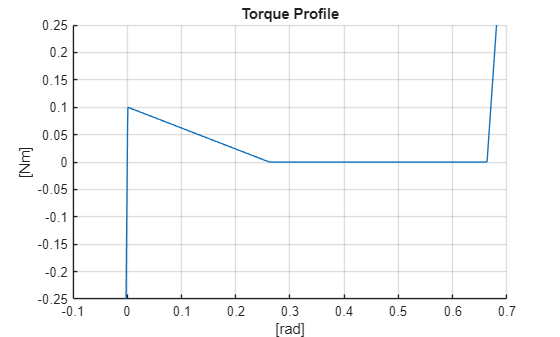

clc
clear
close all

% --- SPRING PARAMS ---
d0 = 27.5e-3;
k = 1.75e3;
d_max = 40e-3;
SF = 1.5;
r0 = d_max/(2);
% ---------------------

% TORQUE PROFILE POINTS (deg)
P = [-0.25   -0.25
     0.1 0.1
     30  0.0
     76  0.0
     78  0.25];
P(:,1) = P(:,1)/2/180*pi;
% ---------------------

x = linspace(min(P(:,1)), max(P(:,1)),1e3); % angle
hx = x(2) - x(1); % discrete step for integration

t = interp1(P(:,1),P(:,2),x); % piecewise linear torque from points in P
dt  = gradient(t, hx); % derivative of the torque profile

% Plotting
figure
hold on
plot(x,t)
title('Torque Profile')
xlabel('[rad]')
ylabel('[Nm]')
grid on

% Torque mechanical work
% > 0: external torque is supplied
% < 0: energy is taken from the spring
T = cumtrapz(x,t);

% Initial energy stored in the spring
Emin = -k*(2*r0-d0)^2/2;

% CONDITION 1: The spring cannot give more energy than what was stored.
min(T) > Emin

ans = logical
   1


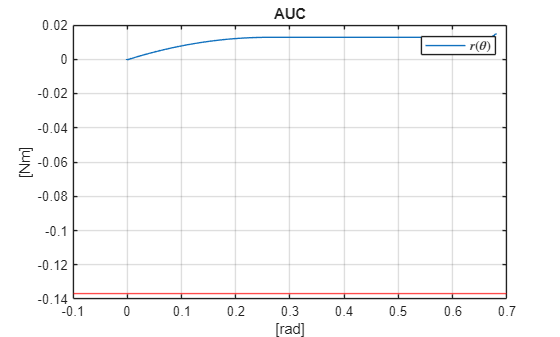


% Plotting
figure
plot(x,T)
title('AUC')
xlabel('[rad]')
ylabel('[Nm]')
grid on
hold on
yline(Emin,'r')
legend({'$r(\theta)$'},"Interpreter","latex","FontSize",10)

r = 0.5*(d0 + ((2*r0 - d0)^2 + 2*T/k).^(1/2)); % support function to generate the profile

% CONDITION 2: The spring cannot exceed it's mamximum length
max(r) < d_max/2

ans = logical
   0


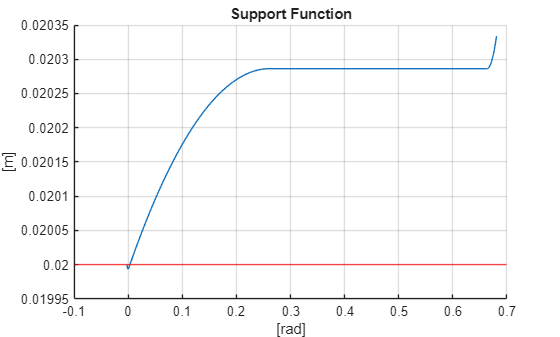


% Plotting
figure
hold on
plot(x,r)
yline(d_max/2,'r')
title('Support Function')
xlabel('[rad]')
ylabel('[m]')
grid on

dr = t./(2*k*((d0 - 2*r0)^2 + (2*T)/k).^(1/2)); % first derivative of r
ddr = dt./(2*k*((d0 - 2*r0)^2 + (2*T)/k).^(1/2)) - t.^2./(2*k^2*((d0 - 2*r0)^2 + (2*T)/k).^(3/2)); % second derivative of r

% for a convex shape generated by a support function r, the curvature is
kappa = r + ddr;

% CONDITION 3: Convex cam <=> curvature > 0;
min(kappa) > 0

ans = logical
   1


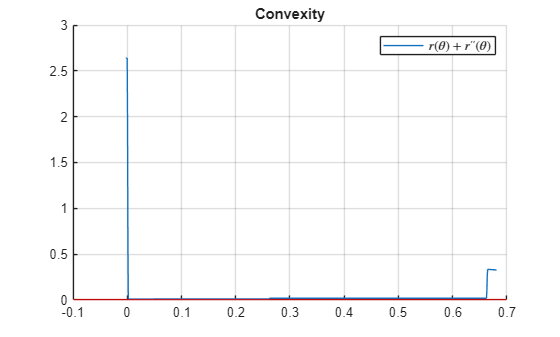


% Plotting
figure
hold on
plot(x,r + ddr)
yline(0,'r')
title('Convexity')
grid on
legend({'$r(\theta) + r''''(\theta)$'},"Interpreter","latex","FontSize",10)

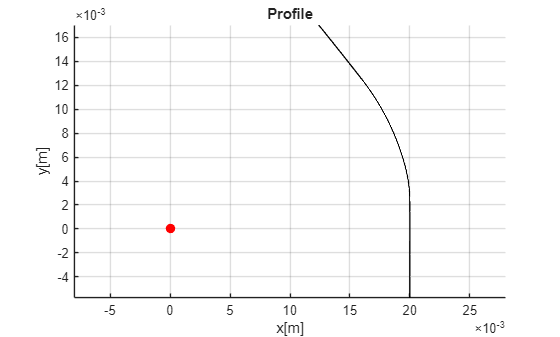

% For a convex curve generated by its support function r, the x,y
% coordinates of the profile are given by
xc = r.*cos(x) - dr.*sin(x);
yc = r.*sin(x) + dr.*cos(x);

% Plotting
figure
hold on
plot(xc,yc,'k','LineWidth',1)
scatter(0,0,50,'filled','or')
title('Profile')
xlabel('x[m]')
ylabel('y[m]')
axis equal
grid on